Create database!

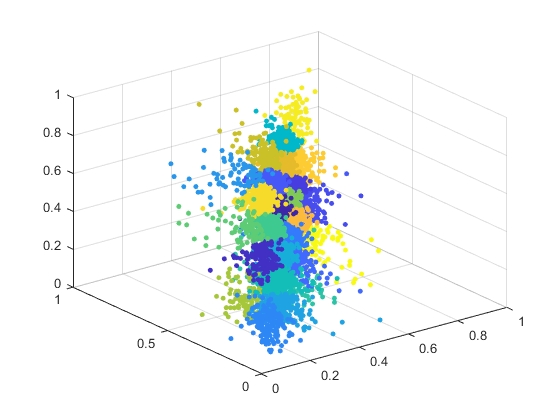

numberOfCluster = 25;
clusterSize = 4;
tinyImgSize = 24;
[smallDatabase, meanSmallDB] = filtering(numberOfCluster,clusterSize,tinyImgSize);

Create reconstructed image from smaller images that comes from the database

% Name of the file (Must be of type jpg)
fileName = 'banana.jpg';
% The size for each "cell" that goes through the image. Recommended size = 8
cellSize = 8;
% Number of 'good-matches' to use SSIM on. Higher = better quality (but also more compute heavy)
n = 5;

% call function to create image
[imgOUT, imgSSIM, imgSNR, imgDE] = image_rec_v1(fileName, smallDatabase, cellSize, n);

% show the final image
imshow(lab2rgb(imgOUT))